# 66010892 อดิศร สมมาตร

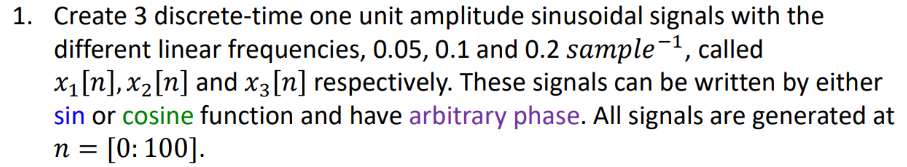

clc
clear

% Linear frequencies (sample^-1)
f = [0.05 0.1 0.2];

A = 1;
n = 0:100;
phi = pi/4;   % arbitrary phase

x1 = A*sin(2*pi*f(1)*n + phi);
x2 = A*sin(2*pi*f(2)*n + phi);
x3 = A*sin(2*pi*f(3)*n + phi);

load('FIR.mat');
hn, n = 0:20;

hn =     0.0318    0.0283    0.0117   -0.0125   -0.0347   -0.0450   -0.0378   -0.0149    0.0152    0.0403    0.0500    0.0403    0.0152   -0.0149   -0.0378   -0.0450   -0.0347   -0.0125    0.0117    0.0283    0.0318


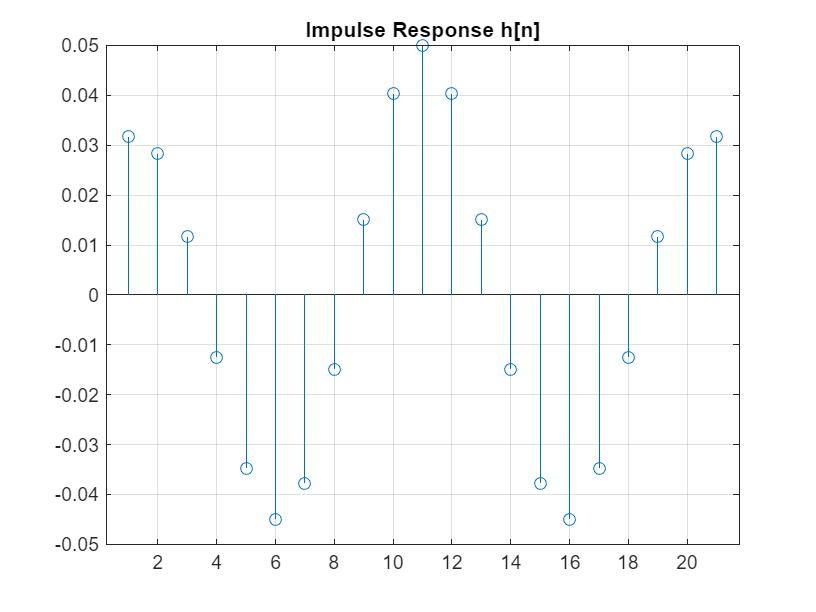

y1 = conv(x1, hn);
y2 = conv(x2, hn);
y3 = conv(x3, hn);

ny = 0:length(y1)-1;   % n = 0:120
figure
stem(hn)
grid on
title('Impulse Response h[n]')

ผลลัพธ์ที่สังเกตได้ (จากกราฟ):

 x_1[n] (f=0.05): สัญญาณเอาต์พุต y_1[n] มีขนาด (Magnitude) ลดลงมากที่สุด

 x_2[n]$ (f=0.1): สัญญาณเอาต์พุต y_2[n] มีขนาดลดลงปานกลาง 

 x_3[n]$ (f=0.2): สัญญาณเอาต์พุต y_3[n] มีขนาดลดลงน้อยที่สุด หรือเกือบเท่าเดิม

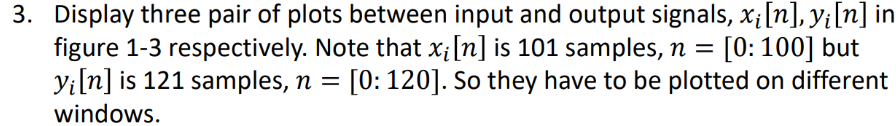

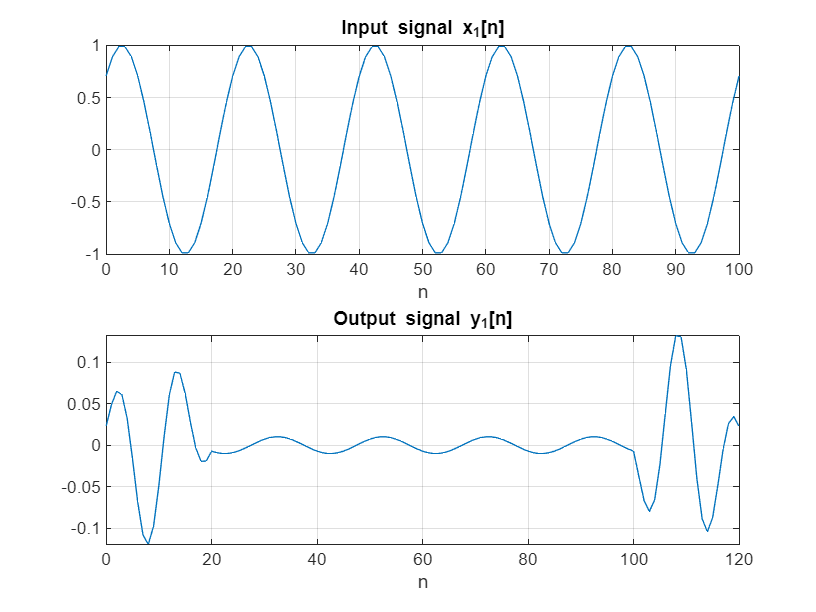

n_x = 0:100;               % input index
n_y = 0:length(y1)-1;     % output index (0:120)

figure(1)

subplot(2,1,1)
plot(n_x, x1)
grid on
title('Input signal x_1[n]')
xlabel('n')

subplot(2,1,2)
plot(n_y, y1)
grid on
title('Output signal y_1[n]')
xlabel('n')

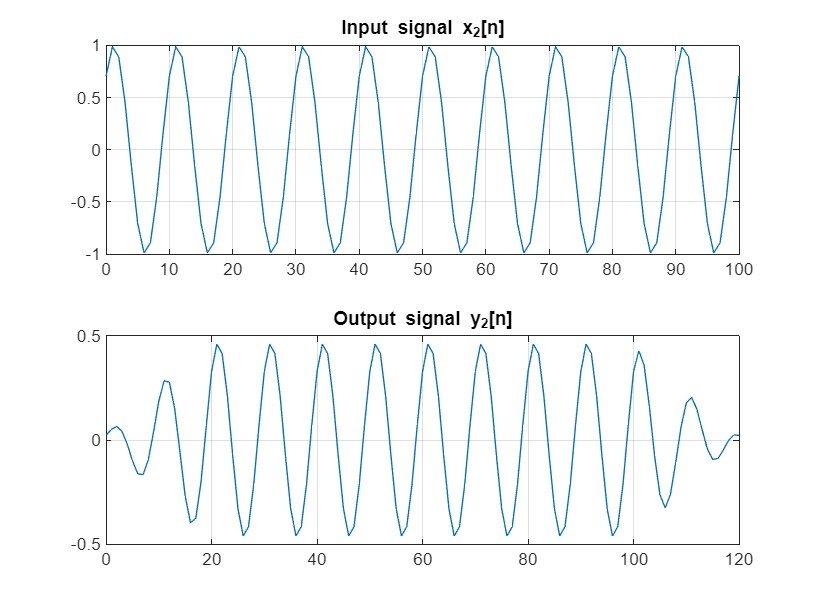


figure(2)

subplot(2,1,1)
plot(n_x, x2)
grid on
title('Input signal x_2[n]')

subplot(2,1,2)
plot(n_y, y2)
grid on
title('Output signal y_2[n]')

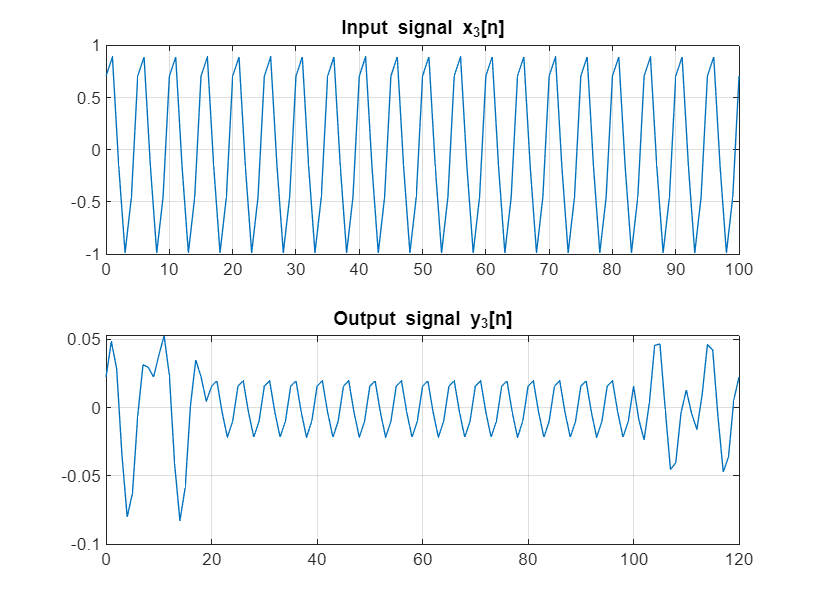


figure(3)

subplot(2,1,1)
plot(n_x, x3)
grid on
title('Input signal x_3[n]')

subplot(2,1,2)
plot(n_y, y3)
grid on
title('Output signal y_3[n]')

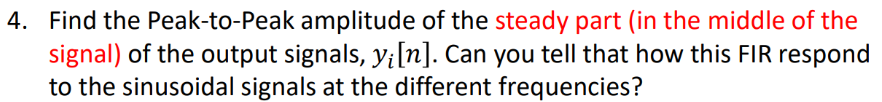

steady = 40:80;

pp_y1 = max(y1(steady)) - min(y1(steady));
pp_y2 = max(y2(steady)) - min(y2(steady));
pp_y3 = max(y3(steady)) - min(y3(steady));

fprintf('FIR Peak-to-Peak:\n')

FIR Peak-to-Peak:


fprintf('y1: %.4f\n', pp_y1)

y1: 0.0201


fprintf('y2: %.4f\n', pp_y2)

y2: 0.9197


fprintf('y3: %.4f\n', pp_y3)

y3: 0.0413


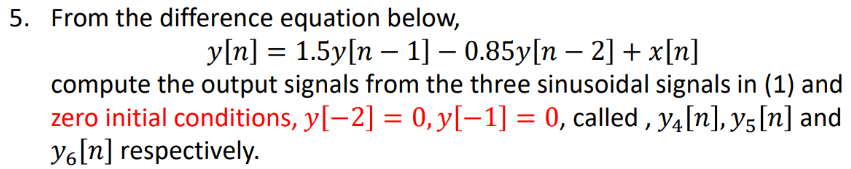

b = 1;
a = [1 -1.5 0.85];

y4 = filter(b, a, x1);
y5 = filter(b, a, x2);
y6 = filter(b, a, x3);
n_x   = 0:100;      % input index
n_yi  = -2:100;     % output index (IIR)
y4_plot = [0 0 y4];
y5_plot = [0 0 y5];
y6_plot = [0 0 y6];


ผลลัพธ์ที่สังเกตได้ (จากกราฟ):

x_1[n] (f=0.05$): สัญญาณเอาต์พุต y_4[n] มีขนาด เพิ่มขึ้น มากที่สุด (Magnitude Gain สูง)

x_3[n] (f=0.2): สัญญาณเอาต์พุต y_6[n] มีขนาด เพิ่มขึ้น น้อยที่สุด (Magnitude Gain ต่ำ)

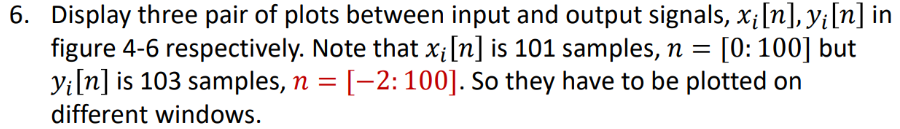

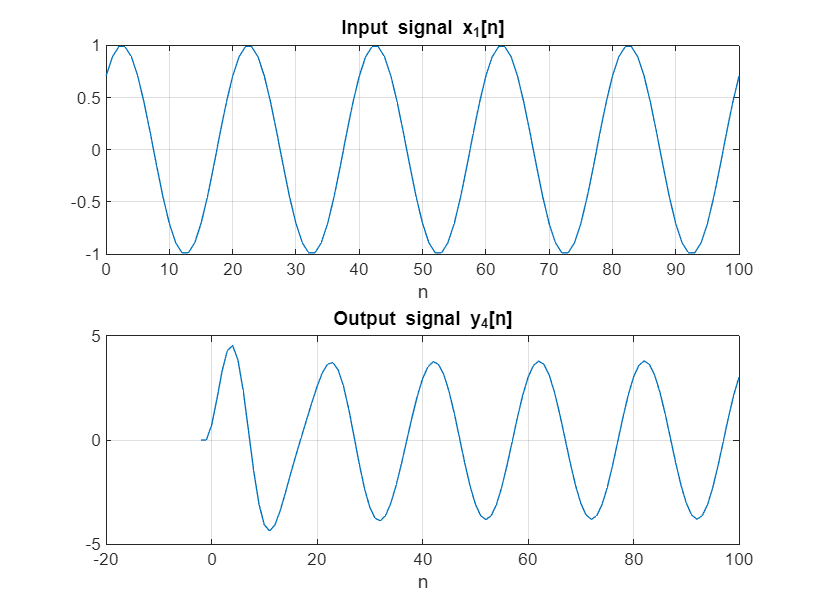

	figure(4)

subplot(2,1,1)
plot(n_x, x1)
grid on
title('Input signal x_1[n]')
xlabel('n')

subplot(2,1,2)
plot(n_yi, y4_plot)
grid on
title('Output signal y_4[n]')
xlabel('n')

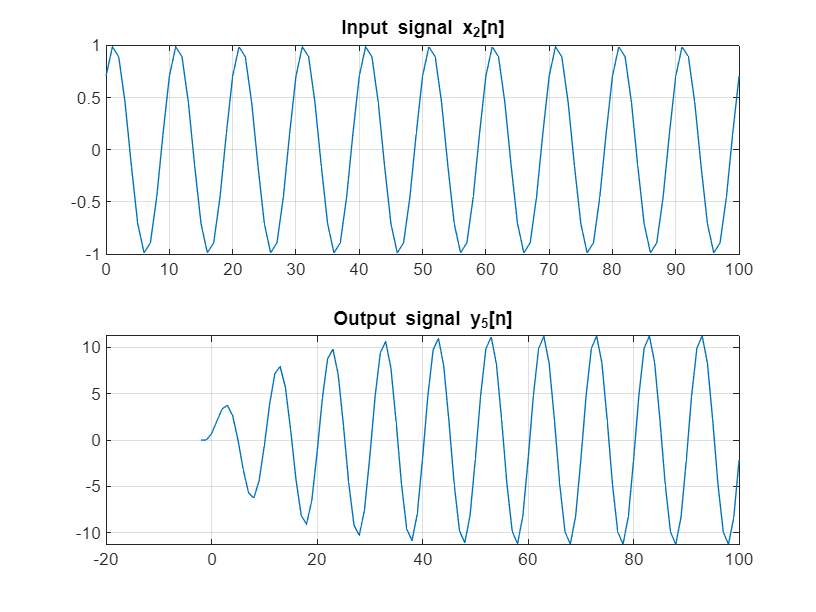

figure(5)

subplot(2,1,1)
plot(n_x, x2)
grid on
title('Input signal x_2[n]')

subplot(2,1,2)
plot(n_yi, y5_plot)
grid on
title('Output signal y_5[n]')

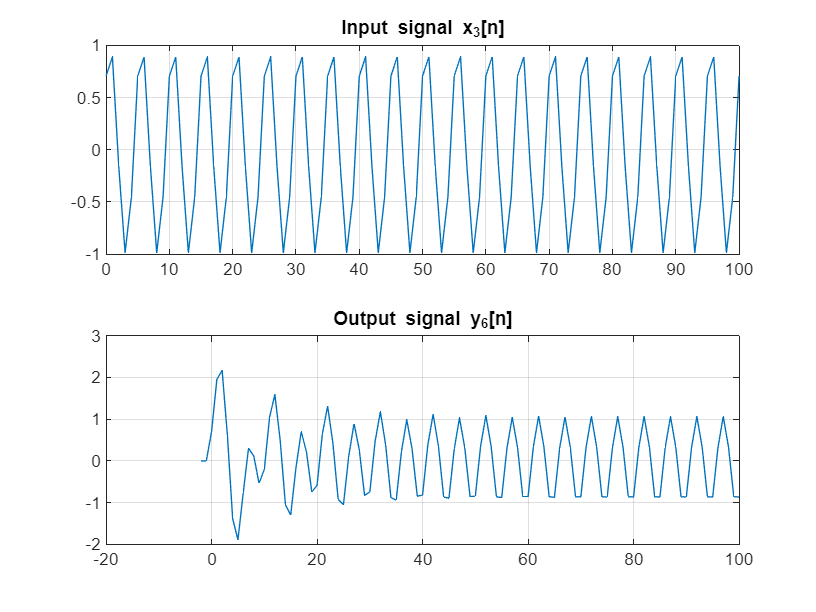


figure(6)

subplot(2,1,1)
plot(n_x, x3)
grid on
title('Input signal x_3[n]')

subplot(2,1,2)
plot(n_yi, y6_plot)
grid on
title('Output signal y_6[n]')

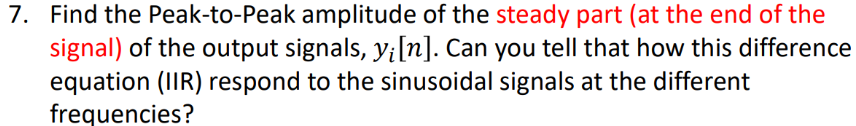

steady_iir = 70:100;

pp_y4 = max(y4(steady_iir)) - min(y4(steady_iir));
pp_y5 = max(y5(steady_iir)) - min(y5(steady_iir));
pp_y6 = max(y6(steady_iir)) - min(y6(steady_iir));

fprintf('IIR Peak-to-Peak:\n')

IIR Peak-to-Peak:


fprintf('y4: %.4f\n', pp_y4)

y4: 7.5893


fprintf('y5: %.4f\n', pp_y5)

y5: 22.5002


fprintf('y6: %.4f\n', pp_y6)

y6: 1.9359


%การสรุปผล (Conclusion)

% FIR System (Convolution): ระบบนี้ทำหน้าที่เป็น High-Pass Filter (HPF) เนื่องจากมีการลดทอนสัญญาณที่ความถี่ต่ำ (f=0.05) มากกว่าที่ความถี่สูง (f=0.2)

% IIR System (Difference Eq.): ระบบนี้ทำหน้าที่เป็น Low-Pass Filter (LPF) เนื่องจากมีการขยายสัญญาณที่ความถี่ต่ำ (f=0.05) มากกว่าที่ความถี่สูง (f=0.2)

%The output signals obtained from the difference equation have longer duration due to the system memory. Therefore, the input and output signals are plotted in separate windows with different time indices.

Save .Fig

studentID = '66010892';
allFigureHandles = findall(0, 'Type', 'figure');
for i = 1:length(allFigureHandles)
    figName = sprintf('%s_Figure%d.fig', studentID, i);
    savefig(allFigureHandles(i), figName);
    disp(['Saved: ' figName]);
end

Saved: 66010892_Figure1.fig
Saved: 66010892_Figure2.fig
Saved: 66010892_Figure3.fig
Saved: 66010892_Figure4.fig
Saved: 66010892_Figure5.fig
Saved: 66010892_Figure6.fig
Saved: 66010892_Figure7.fig
